# Bed load time series

This code processes at the same time all the Logfiles that are stored in one folder. Then, it computes the sediment transport rate at the specified frequency and builds a time series for the experiment represented by these files. 

It plots the time series of sediment transport rates and accumulated transport for the entire experiment. 

Optional: Allows you to plot the time series of sediment transport rates and accumulated transport for each file. 

close all

## Parameters

Directory where logfiles of force sensor are stored.

filesPath = "E:\00.EXPERIMENTS\00_bedload\Experiment02"; % Where the Logfiles are stored

plotSedRate = false;            % Plot sediment rate timeseries for each file
plotCumSed = false;             % Plot accumulated sediment timeseries for each file
originalTimeWindow = 1;         % What is the frequency at which the data was written in the logfile
lag = 60;                       % The step for taking values from the full resolution table. E.g, if you select 60, it will take one value each 60 seconds.

***DO NOT MODIFY FROM THIS POINT DOWN***

### Loop over all files

filenames = dir(fullfile(filesPath, '*.txt'));  % List of logfiles to process
allBLTable = [];                                % Empty output table
allAggTable = [];                               % Empty output table

for i=1:length(filenames)
    % Create ensembled timetable and plot individual plots for each serie
    [bedloadTable, aggTable] = getBedload(fullfile(filenames(i).folder, filenames(i).name(1:end-4)), plotSedRate, plotCumSed, originalTimeWindow, lag);

    if i==1 % The first one is copied intact
        allBLTable = [allBLTable; bedloadTable];
        allAggTable = [allAggTable; aggTable];
    else    % For the rest we modify the time to make it a continuous time serie
        bedloadTable.dt = bedloadTable.dt+allBLTable.dt(end)+ seconds(originalTimeWindow);
        aggTable.dt = aggTable.dt+allAggTable.dt(end)+ seconds(lag);
        aggTable.GlobalCumBedload = aggTable.GlobalCumBedload+allAggTable.GlobalCumBedload(end);

        allBLTable = [allBLTable; bedloadTable];
        allAggTable = [allAggTable; aggTable];
    end
end

### Plotting

Plotting the resulting complete time series for the experiment.

#### Bed load rate

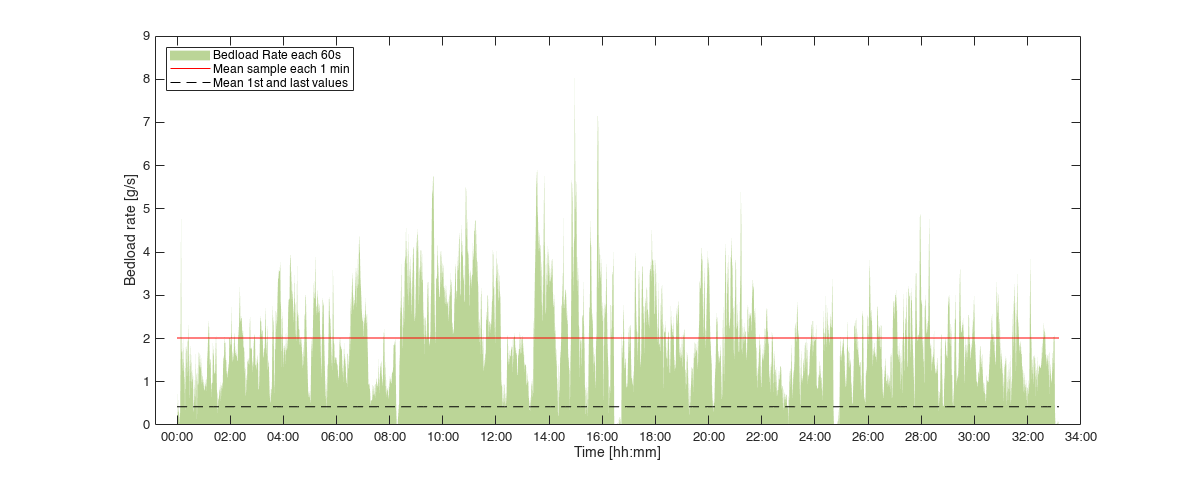

figure('Position', [10 10 1500 600])
area(allAggTable.dt, allAggTable.PositiveBedloadRate, DisplayName=strcat("Bedload Rate each ",num2str(lag), "s"), FaceColor="#77AC30",EdgeColor="none", FaceAlpha=0.5)
hold on 
plot(allAggTable.dt, ones(height(allAggTable),1)*mean(allAggTable.PositiveBedloadRate),'r-', DisplayName='Mean sample each 1 min')
plot(allAggTable.dt, ones(height(allAggTable),1)*(allBLTable.CumBedload(end)-allBLTable.CumBedload(1))/length(allBLTable.PositiveBedloadRate),'k--', DisplayName='Mean 1st and last values')
xtickformat('hh:mm')
xlabel("Time [hh:mm]")
ylabel("Bedload rate [g/s]")
legend(Location="northwest")

#### Accumulated bed load - per day

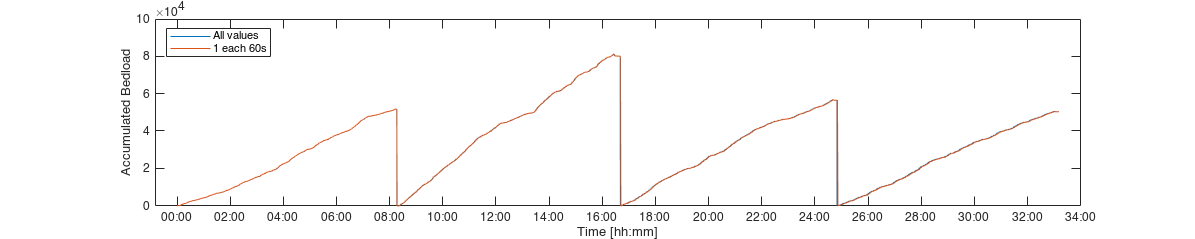

figure('Position', [10 10 1500 300])
plot(allBLTable.dt, allBLTable.CumBedload, DisplayName="All values")
hold on
plot(allAggTable.dt, allAggTable.CumBedload, DisplayName="1 each 60s")
xtickformat('hh:mm')
xlabel("Time [hh:mm]")
ylabel("Accumulated Bedload")
legend(Location="northwest")

#### Accumulated bed load - Complete experiment

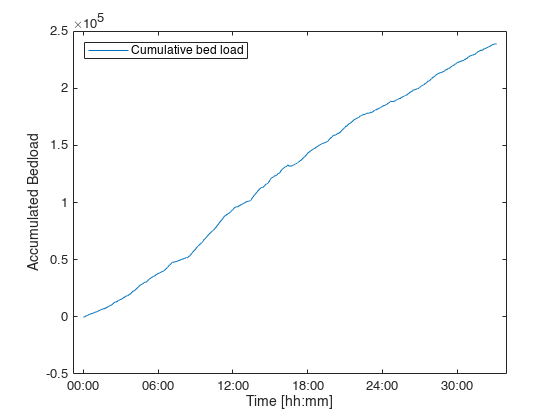

figure()
plot(allAggTable.dt, allAggTable.GlobalCumBedload, DisplayName="Cumulative bed load")
xtickformat('hh:mm')
xlabel("Time [hh:mm]")
ylabel("Accumulated Bedload")
legend(Location="northwest")

### Exporting time series to Matfile

save("timeSeries.mat","allBLTable","allAggTable");